# Estudos e Resultados

clear

## Dados Longitudinais

% Rodar dados_logitudinal.py para os 5 valores de u
load dados_0_05.mat
load dados_0_10.mat
load dados_0_15.mat
load dados_0_20.mat
load dados_0_25.mat

Ts = mean(gradient(t05))

Ts = 0.0500

Tf = max(t05)

Tf = 15.0000

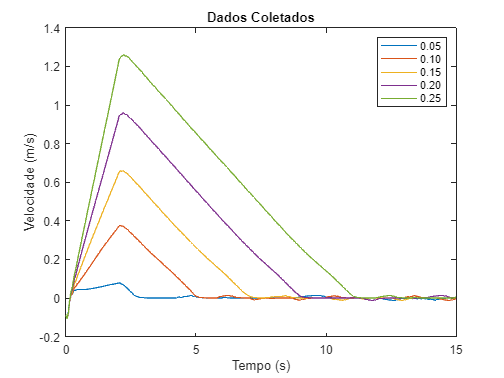

figure
plot(t05, [v05; v10; v15; v20; v25])
title("Dados Coletados")
xlabel("Tempo (s)")
ylabel("Velocidade (m/s)")
xlim([0 Tf])
legend(["0.05", "0.10", "0.15", "0.20", "0.25"])

Modelagem por aceleração

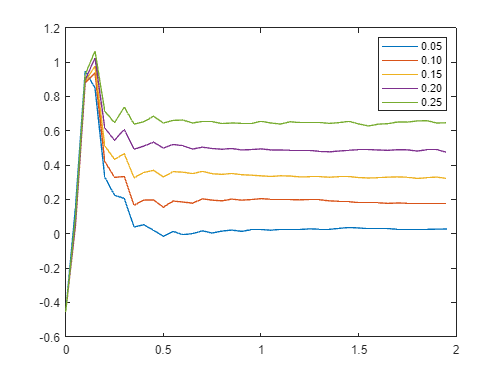

idx = t25 <= 2;
time = t25(idx);

a05 = gradient(v05, t05); a05 = a05(idx);
a10 = gradient(v10, t10); a10 = a10(idx);
a15 = gradient(v15, t15); a15 = a15(idx);
a20 = gradient(v20, t20); a20 = a20(idx);
a25 = gradient(v25, t25); a25 = a25(idx);

figure
plot(time, [a05; a10; a15; a20; a25])
legend(["0.05", "0.10", "0.15", "0.20", "0.25"])
xlim([0 2])

u = @(amplitude) amplitude*ones(size(time));
data10 = iddata(a10', u(0.10)', Ts);
data15 = iddata(a15', u(0.15)', Ts);
data20 = iddata(a20', u(0.20)', Ts);
data25 = iddata(a25', u(0.25)', Ts);

Ga = tfest(data25, 1, 0)

Ga =
  From input "u1" to output "y1":
    71.8
  ---------
  s + 26.87
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 0
   Number of free coefficients: 2
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using TFEST on time domain data "data25".
Fit to estimation data: 53.35%                     
FPE: 0.01121, MSE: 0.009647                        
 
Model Properties


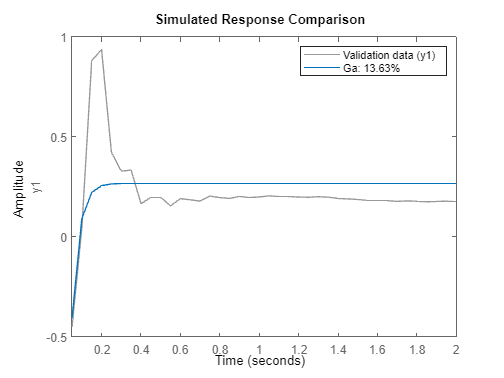

compare(data10, Ga)

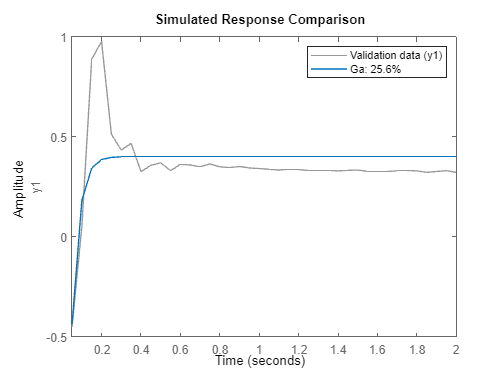

compare(data15, Ga)

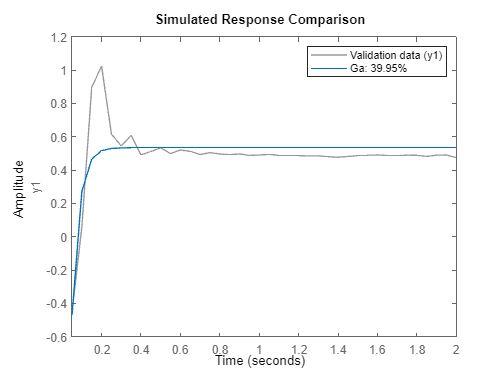

compare(data20, Ga)

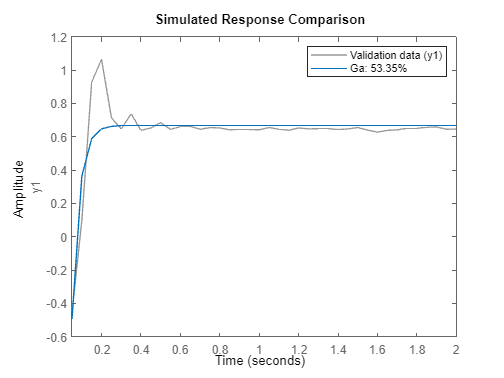

compare(data25, Ga)

## Modelo de velocidade

Gad = c2d(Ga, Ts, 'tustin')
Gv = c2d(tf(1, [1 0]), Ts, 'tustin') * Ga

Gv =
 
  From input "u1" to output:
     0.05013 + 0.05013 z^-1
  ----------------------------
  1 - 1.251 z^-1 + 0.2509 z^-2
 
Sample time: 0.05 seconds
Discrete-time transfer function.
Model Properties


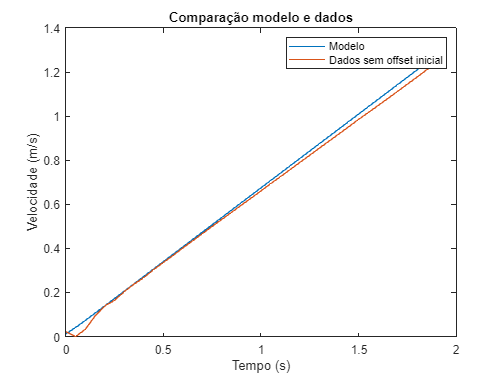

figure
plot(time, lsim(Gv, u(0.25), time), time, v25(idx) - min(v25(idx)))
title("Comparação modelo e dados")
legend(["Modelo", "Dados sem offset inicial"])
xlabel("Tempo (s)")
ylabel("Velocidade (m/s)")

## Controlador Longitudinal

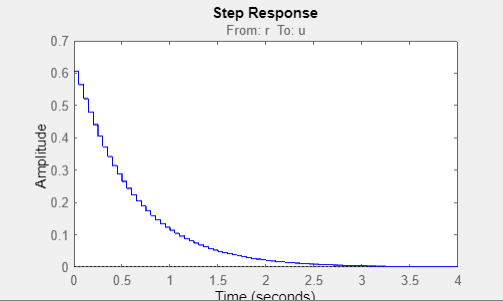

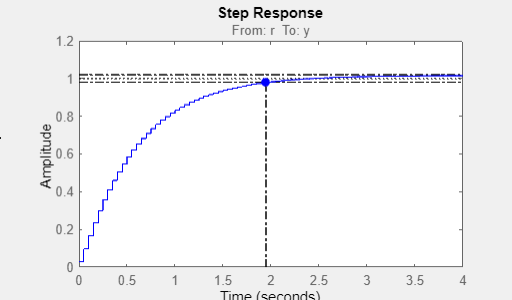

C = 0.62429 * tf([1 -0.9985], [1 -1], Ts)

C =
 
  0.6243 z - 0.6234
  -----------------
        z - 1
 
Sample time: 0.05 seconds
Discrete-time transfer function.
Model Properties


Gmf = feedback(C*Gv, 1)

Gmf =
 
  From input "u1" to output:
     0.0313 + 4.694e-05 z^-1 - 0.03125 z^-2
  ---------------------------------------------
  1.031 - 2.251 z^-1 + 1.471 z^-2 - 0.2509 z^-3
 
Sample time: 0.05 seconds
Discrete-time transfer function.
Model Properties


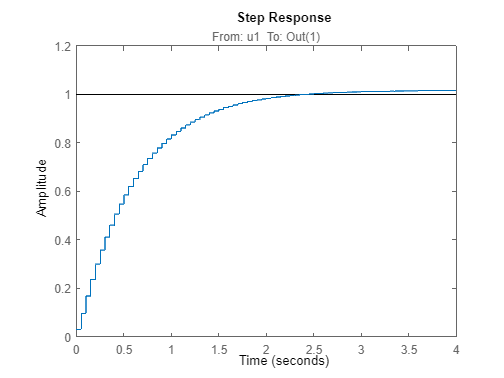

step(Gmf)

stepinfo(Gmf)

ans = struct with fields:
         RiseTime: 1.2000
    TransientTime: 2.0000
     SettlingTime: 1.9500
      SettlingMin: 0.9062
      SettlingMax: 1.0161
        Overshoot: 1.6092
       Undershoot: 0
             Peak: 1.0161
         PeakTime: 4.8000


syms z
Csyms = 0.62429*(z - 0.9985)/(z - 1);
[N, D] = numden(Csyms);
Nc = eval(coeffs(N));
Dc = eval(coeffs(D));
Nc = Nc./(Dc(1));
Dc = Dc./(Dc(1));
M = idpoly(Dc, Nc, 'NoiseVariance', 0)

M =
Discrete-time ARX model: A(z)y(t) = B(z)u(t)
  A(z) = 1 - z^-1                           
                                            
  B(z) = 0.6234 - 0.6243 z^-1               
                                            
Sample time: unspecified
  
Parameterization:
   Polynomial orders:   na=1   nb=2   nk=0
   Number of free coefficients: 3
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                         
Created by direct construction or transformation. Not estimated.
 
Model Properties


#### Equação diferença a ser implementada no código


$$u\left\lbrack k\right\rbrack =u\left\lbrack k-1\right\rbrack +0\ldotp 6234\cdot e\left\lbrack k\right\rbrack -0\ldotp 6243\cdot e\left\lbrack k-1\right\rbrack$$
